clear all
close all
clc
% 
% syms d1 L1 L2 L3

d1 = 1;
L1 = 1;
L2 = 1;
L3 = 1;

%a utiliser pour obtenir l'expression litérale du FK
syms q1 q2 q3 q4 q5;

% angles des liaisons pivots en RAD
Q1 =0 *3.1415/180;
Q2 =0 *3.1415/180;
Q3 =0 *3.1415/180;
Q4 =0 *3.1415/180;
Q5 =0 *3.1415/180;

% Q1 = q1*180/pi;
% Q2 = q2*180/pi;
% Q3 = q3*180/pi;
% Q4 = q4*180/pi;
% Q5 = q5*180/pi;


%calculate the matrixes
T_01 = create_distal_T_ij(0 , 0    , 0  ,0);
T_12 = create_distal_T_ij(0 , 90 ,   d1 ,Q1);
T_23 = create_distal_T_ij(L1, 0    , 0  ,Q2);
T_34 = create_distal_T_ij(L2, 0    , 0  ,Q3);
T_45 = create_distal_T_ij(0 , -90,   0  ,Q4);
T_56 = create_distal_T_ij(0 , 0    , L3 ,Q5);

T_13 = T_12 *T_23;
T_14 = T_12 *T_23  *T_34;
T_15 = T_12 *T_23  *T_34 *T_45;
T_16 = T_12 *T_23  *T_34 *T_45 *T_56;

%a utiliser pour obtenir l'expression litérale du FK
%sympref('AbbreviateOutput', false)

%les positions de chaque liaison
x1=0;
y1=0;
z1=0;

x2=T_12(1,4);
y2=T_12(2,4);
z2=T_12(3,4);

x3=T_13(1,4);
y3=T_13(2,4);
z3=T_13(3,4);

x4=T_14(1,4);
y4=T_14(2,4);
z4=T_14(3,4);

x5=T_15(1,4);
y5=T_15(2,4);
z5=T_15(3,4);

x6=T_16(1,4);
y6=T_16(2,4);
z6=T_16(3,4);

%vecteurs avec toutes les positions des joints
xx=[x1;x2;x3;x4;x5;x6];
yy=[y1;y2;y3;y4;y5;y6];
zz=[z1;z2;z3;z4;z5;z6];

## **Plotting**


figure (1)
set(1,'position')

  0×0 empty cell array



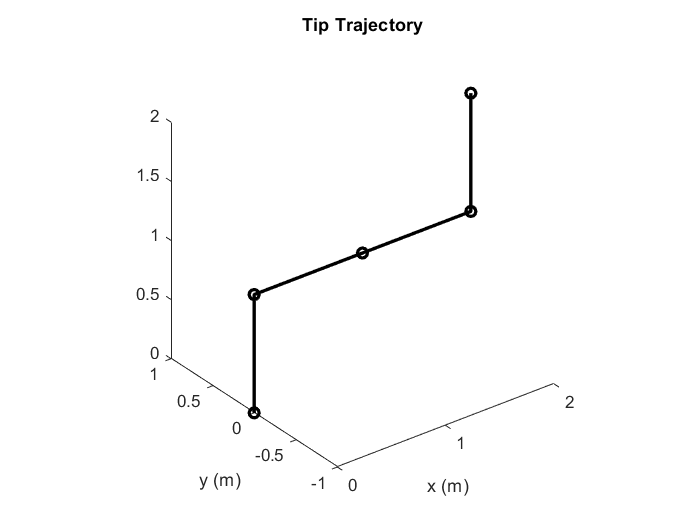


plot3(xx,yy,zz,'ko-','Linewidth',2)  % plot the  position of the robot
axis equal
hold on
title('Tip Trajectory') ; xlabel('x (m)') ; ylabel('y (m)') ;
hold off


% %en 2D mais c'est nul
% figure (2) 
% set(2,'position')
% 
% plot(xx,yy,'ko-','Linewidth',2)
% axis equal
% hold on
% 
% xlabel('x (m)') ; ylabel('y (m)') ;
% axis([-2 2 -2 2])
% hold off

%% Workspace
L_q1 = linspace(0,360,360) ;
L_q2 = linspace(0,360,360) ;

L_c1 = cos(L_q1);
L_s1= sin(L_q1);
cw12 = zeros(360,360) ;
sw12 = zeros(360,360);

%% Plot the workspace of the robot
figure (3)
set(3,'position',[1243 190 560 420])

xwork = zeros(360,360) ; % reserving space for the variables, because
ywork = zeros(360,360) ; % otherwise they would be created later within a loop.

for i = 1:360	% for q1
    for j = 1:360   % for q2
        cw12(i,j) = cos(q1(1,i)+ q2(1,j));
        sw12(i,j) = sin(q1(1,i)+ q2(1,j));
        xwork(i,j) = l1*cw1(i)+l2*cw12(i,j) ;
        ywork(i,j) = l1*sw1(i)+l2*sw12(i,j) ;
    end
end

Unable to perform assignment because value of type 'sym' is not convertible to 'double'.

Caused by:
    Error using symengine
    Unable to convert expression containing symbolic variables into double array. Apply 'subs' function first to substitute values for variables.


plot(xwork,ywork,'.')
axis equal


Workspace

% angles des liaisons pivots en RAD

xwork = zeros(19,19,19,19,19) ; % reserving space for the variables, because
ywork = zeros(19,19,19,19,19) ; % otherwise they would be created later within a loop.
zwork = zeros(19,19,19,19,19)

zwork = zwork(:,:,1,1,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0    


for q1 = 0: 20: 360
    for q2 = 0:20:360
        for q3 = 0:20:360
            for q4 = 0:20:360
                for q5 = 0:20:360
                    L_q = [q1 q2 q3 q4 q5];
                    pos = forward_kinematics(L_q);
                    xwork(1+q1/20,1+q2/20,1+q3/20,1+q4/20,1+q5/20) = pos(1);
                    ywork(1+q1/20,1+q2/20,1+q3/20,1+q4/20,1+q5/20) = pos(2);
                    zwork(1+q1/20,1+q2/20,1+q3/20,1+q4/20,1+q5/20) = pos(3);
                end
            end
        end
    end    
end

figure (3)
set(3,'position')

  0×0 empty cell array




plot3(xwork,ywork,zwork,'.')  % plot the  workspace of the robot

Error using plot3
Data cannot have more than 2 dimensions.

axis equal
hold on
title('Workspace') ; xlabel('x (m)') ; ylabel('y (m)') ;
hold off


a = 0: 20: 360

a =      0    20    40    60    80   100   120   140   160   180   200   220   240   260   280   300   320   340   360


a = a/20

a =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18
